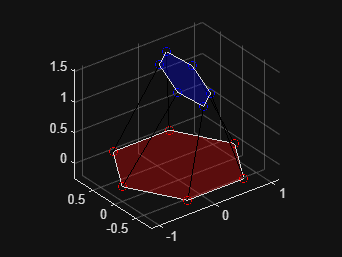

clc;
clear all;

animate_stewart_platform([0.5, 0.5, 1], [pi/6, pi/6, pi/6]);

function animate_stewart_platform(position, orientation)
    % Number of points on the platform and base
    num_points = 6;

    % Define the base platform joint coordinates (assuming hexagonal configuration)
    base_radius = 1;
    theta_base = linspace(0, 2*pi, num_points + 1);
    base_points = base_radius * [cos(theta_base(1:end-1)); sin(theta_base(1:end-1)); zeros(1, num_points)];
    
    % Define the top platform joint coordinates (assuming hexagonal configuration)
    platform_radius = 0.5;
    theta_platform = linspace(0, 2*pi, num_points + 1);
    platform_points = platform_radius * [cos(theta_platform(1:end-1)); sin(theta_platform(1:end-1)); zeros(1, num_points)];

    % Define figure for animation
    figure;
    hold on;
    axis equal;
    grid on;
    view(3);
    
    % Plot base platform
    plot3(base_points(1, :), base_points(2, :), base_points(3, :), 'ro');
    fill3(base_points(1, :), base_points(2, :), base_points(3, :), 'r', 'FaceAlpha', 0.3);
    
    % Create a handle for the top platform plot
    platform_plot = plot3(platform_points(1, :), platform_points(2, :), platform_points(3, :), 'bo');
    platform_fill = fill3(platform_points(1, :), platform_points(2, :), platform_points(3, :), 'b', 'FaceAlpha', 0.3);
    
    % Calculate and animate the movement
    for t = linspace(0, 1, 100)
        % Interpolated position and orientation
        interp_position = position * t;
        interp_orientation = orientation * t;

        % Apply translation and rotation
        R = eul2rotm(interp_orientation, 'XYZ');
        transformed_points = R * platform_points;
        transformed_points = transformed_points + interp_position';

        % Update the plot
        set(platform_plot, 'XData', transformed_points(1, :), 'YData', transformed_points(2, :), 'ZData', transformed_points(3, :));
        set(platform_fill, 'Vertices', transformed_points');

        % Clear previous lines
        if exist('line_handles', 'var')
            delete(line_handles);
        end
        line_handles = gobjects(1, num_points);
        
        % Update the actuator lines
        for i = 1:num_points
            line_handles(i) = line([base_points(1, i), transformed_points(1, i)], ...
                                   [base_points(2, i), transformed_points(2, i)], ...
                                   [base_points(3, i), transformed_points(3, i)], 'Color', 'k');
        end
        
        drawnow;
    end
end

function R = eul2rotm(eul, seq)
    % Converts Euler angles to rotation matrix
    R = eye(3);
    for i = 1:length(seq)
        switch seq(i)
            case 'X'
                R = R * [1, 0, 0; 0, cos(eul(i)), -sin(eul(i)); 0, sin(eul(i)), cos(eul(i))];
            case 'Y'
                R = R * [cos(eul(i)), 0, sin(eul(i)); 0, 1, 0; -sin(eul(i)), 0, cos(eul(i))];
            case 'Z'
                R = R * [cos(eul(i)), -sin(eul(i)), 0; sin(eul(i)), cos(eul(i)), 0; 0, 0, 1];
        end
    end
end
